# **A1-Feedforward Neural NetworkE_Sys_output**

**工作流程:**

**1.在SystemVue中运行DPD Extration流，获得Model System的原始数据**

**2.在MATLAB中运行前两节，运行后获得应用于实测的模型**

**3.在SystemVue中运行DPD Validation流，获得Model System的实测数据**

**4.在MATLAB中运行第三节，对比模拟和实测结果**

一个重要的点——每次的input是固定的，且对于两个system相同，甚至于每一次的original的output野相同

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Original System----------------------------

此模型是完全固定的！

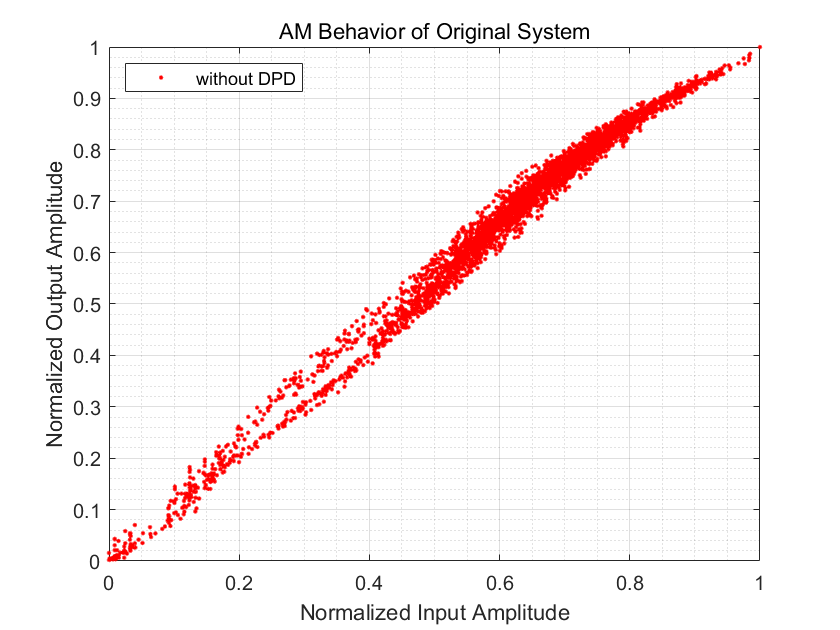

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
Original_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 模型仿真
[U1,D1]=Power_Divider(Original_input);
U2=PA_1(U1);
U3=PA_3(U2);
D2=PA_2(D1);
D3=PA_4(D2);
Original_output_sim=Power_Combiner(U3,D3);
% 性能评估
err=abs(Original_output_sim-Original_output); %模型本身的误差
Plot_AM(Original_input,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim= NMSE_dB(Original_input,Original_output_sim);
nmse_act = NMSE_dB(Original_input,Original_output);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -16.688242 dB


fprintf('不使用DPD，系统的NMSE实测结果为 %f dB\n', nmse_act);

不使用DPD，系统的NMSE实测结果为 -16.688242 dB


## Model A1 System：Feedforward Neural Network

**Train Model**

% 根据需要选取原始数据
PA1_x_i=Data_matrix(:,3);PA1_x_q=Data_matrix(:,4);
PA1_y_i=Data_matrix(:,7);PA1_y_q=Data_matrix(:,8);
PA1_input = PA1_x_i + 1i * PA1_x_q; 
PA1_output = PA1_y_i + 1i * PA1_y_q; 

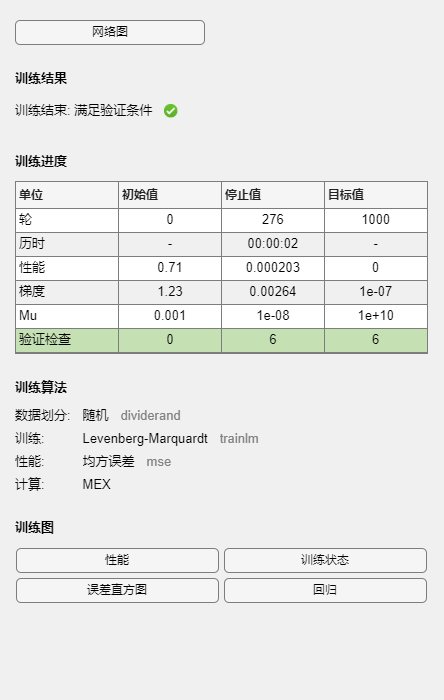

%% 设置输入/输出矩阵
M=2; % 记忆深度
X1 = zeros(2*(M + 1), dim-M); 
for j = 1:length(PA1_y_i) - M
    X1(:, j) = [PA1_y_i(j : j + M); PA1_y_q(j : j + M)];% 前M+1行是PA1_output实部，后M+1行是PA1_output虚部
end 
Y = [PA1_x_i(M + 1 : end)'; PA1_x_q(M + 1 : end)']; % 第1行是PA1_input实部，第2行是PA1_input虚部

%% 调整参数和训练模型
net = feedforwardnet(5);% 神经元数量 
trained_net = train(net, X1, Y);

save('Algorithm_A/NN.mat', 'trained_net');

%% 单级模拟
Y_pred = sim(trained_net, X1); 
save('DPD_data/TestData.mat','X1','Y','Y_pred');
a = Y_pred(1, :) + Y_pred(2, :) * 1i; % PA输出预测值
b = Y(1, :) + Y(2, :) * 1i; % PA输出值（）
nmse_DPD = NMSE_dB(a, b);
fprintf('DPD的模拟NMSE为 %f dB', nmse_DPD);

DPD的模拟NMSE为 -26.571892 dB

**Test Model**

仿真结果一般会比实测结果小2dB左右。

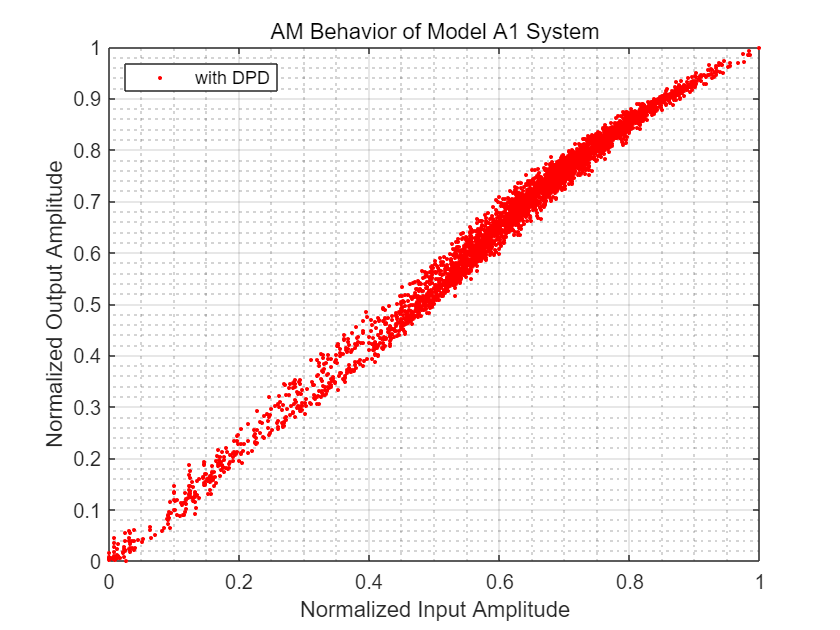

% 读新系统的输出
[Sys_x_i,Sys_x_q,Sys_y_i,Sys_y_q,dim]=ReadFile_Model('A');
Sys_input = Sys_x_i + 1i * Sys_x_q; 
Sys_output = Sys_y_i + 1i * Sys_y_q; 

%% 系统模拟
[S_U1,S_D1]=Power_Divider(Sys_input);
S_U1_DPD= DPD_A1_M(S_U1,2);
S_U2    = PA_1(S_U1_DPD);
S_U3    = PA_3(S_U2);
S_D2    = PA_2(S_D1);
S_D3    = PA_4(S_D2);
Sys_output_sim=Power_Combiner(S_U3,S_D3);

% 性能评估
err=abs(Sys_output_sim-Sys_output); %模型本身的误差
Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Model A1 System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model A1，系统的NMSE仿真结果为 %f dB\n', nmse_sim);% 目标是18.5左右

使用Model A1，系统的NMSE仿真结果为 -16.282468 dB
